#### Interpretation der Parameter in der Differentialgleichung:

Durch ein paar einfache Literaturrecherche stellt man schnell fest, dass das in der Aufgabenstellung angegebene Modell dem SI-Modell (Susceptible-Infective Model) im Gebiet der Epidemiologie entspricht. Nach dem Gegenüberstellen der Differentialgleichungen in den zwei Modellen ergibt sich bezüglich der Parameter folgendes:

k = sqrt(r * c * N), 

mit r als [Replikationsrate](https://de.wikipedia.org/wiki/Replikationsrate), c als Wechselwirkungsterm und N als die Gesamtbevölkerung.

clc
close 
clear

%% 

model = 'Ausbreitungsmodell';
load_system(model)
%Simulink.BlockDiagram.buildRapidAcceleratorTarget(model);
%in_k = Simulink.SimulationInput(model);
%in = in.setModelParameter('SimulationMode', 'rapid-accelerator');
%in_k = in_k.setModelParameter('EndTime', 100);

#### Bitte verändern Sie die Parameterwerte des Problems, so dass sich interessante Zustände (stabiles/instabiles Systemverhalten) ergeben. Beschreiben Sie kurz, ob eine solche Parameterkombination möglich ist. 

- Veränderung y0


%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
y0 = 0.01:0.05:0.61;

for p = 1:1:length(y0)
    in_y0(p) = Simulink.SimulationInput(model);
    in_y0(p) = in_y0(p).setVariable('y0', y0(p), 'Workspace', 'Ausbreitungsmodell');
    in_y0(p) = in_y0(p).setVariable('k', 0.1, 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_y0, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[14-Feb-2021 02:19:01] Checking for availability of parallel pool...
[14-Feb-2021 02:19:01] Running simulations...
[14-Feb-2021 02:19:01] Completed 1 of 13 simulation runs
[14-Feb-2021 02:19:01] Completed 2 of 13 simulation runs
[14-Feb-2021 02:19:01] Completed 3 of 13 simulation runs
[14-Feb-2021 02:19:01] Completed 4 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 5 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 6 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 7 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 8 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 9 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 10 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 11 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 12 of 13 simulation runs
[14-Feb-2021 02:19:02] Completed 13 of 13 simulation runs


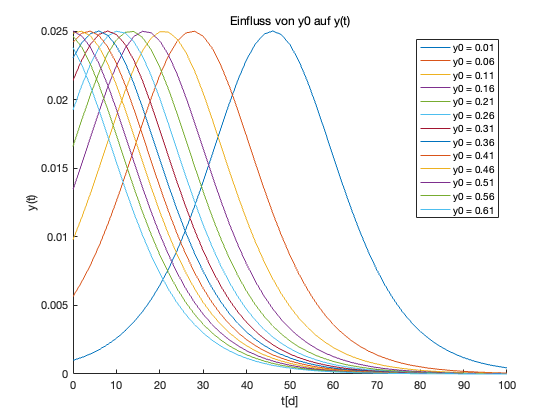


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_y0)
xlabel('t[d]')
ylabel('y(t)')
title('Einfluss von y0 auf y(t)')
saveas(gcf,fullfile('images', 'yt_y0'), 'jpeg')

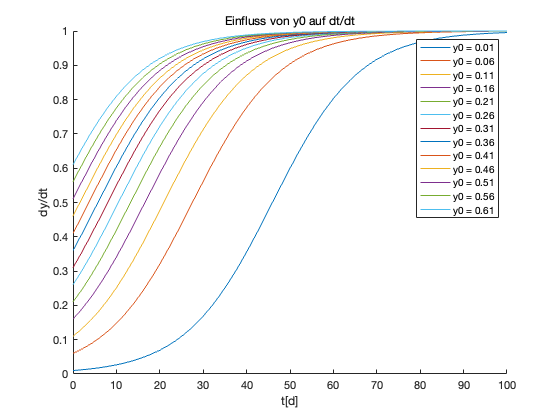


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_y0)
xlabel('t[d]')
ylabel('dy/dt')
title('Einfluss von y0 auf dt/dt')
saveas(gcf,fullfile('images', 'dydt_y0'), 'jpeg')

 2. Veränderung k

%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
k = 0.05:0.05:0.3;

for p = 1:1:length(k)
    in_k(p) = Simulink.SimulationInput(model);
    in_k(p) = in_k(p).setVariable('k', k(p), 'Workspace', 'Ausbreitungsmodell');
    in_k(p) = in_k(p).setVariable('y0', 0.01, 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_k, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[14-Feb-2021 02:19:05] Checking for availability of parallel pool...
[14-Feb-2021 02:19:05] Running simulations...
[14-Feb-2021 02:19:05] Completed 1 of 6 simulation runs
[14-Feb-2021 02:19:05] Completed 2 of 6 simulation runs
[14-Feb-2021 02:19:05] Completed 3 of 6 simulation runs
[14-Feb-2021 02:19:05] Completed 4 of 6 simulation runs
[14-Feb-2021 02:19:05] Completed 5 of 6 simulation runs
[14-Feb-2021 02:19:05] Completed 6 of 6 simulation runs


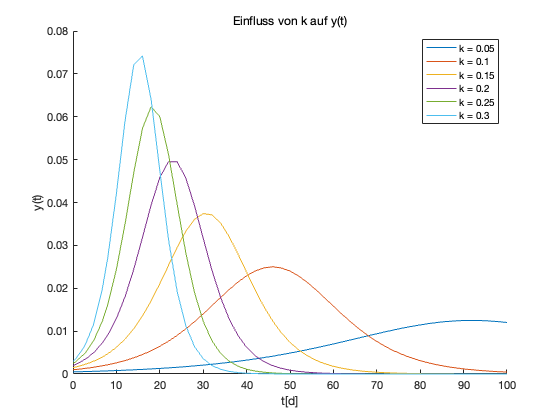


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText_k{p} = ['k = ', num2str(k(p))];
end
legend(legendText_k)
xlabel('t[d]')
ylabel('y(t)')
title('Einfluss von k auf y(t)')
saveas(gcf,fullfile('images', 'yt_k'), 'jpeg')

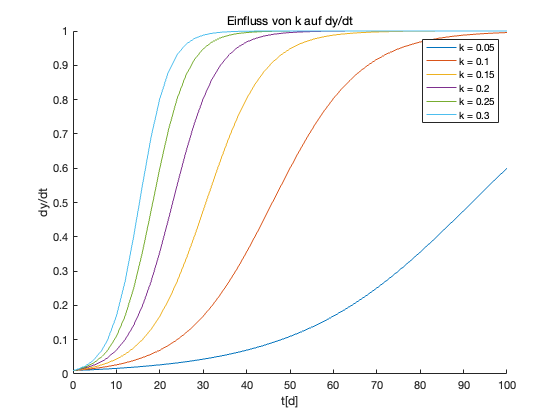


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_k{p} = ['k = ', num2str(k(p))];
end
legend(legendText_k)
xlabel('t[d]')
ylabel('dy/dt')
title('Einfluss von k auf dy/dt')
saveas(gcf,fullfile('images', 'dydt_k'), 'jpeg')

3. Rrki berechnen

Eine *Reproduktionsrate* ist bei der [COVID-19-Pandemie](https://de.wikipedia.org/wiki/COVID-19-Pandemie)  gemäß dem [Robert Koch-Institut](https://de.wikipedia.org/wiki/Robert_Koch-Institut) Rrki[[3]](https://de.wikipedia.org/wiki/SI-Modell#cite_note-4)[[4]](https://de.wikipedia.org/wiki/SI-Modell#cite_note-5) auch R-Wert genannt, bedeutend geworden:

 mit s = 4 und t ≥ 2s.

%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
y0 = 0.005:0.005:0.02;

for p = 1:1:length(y0)
    in_Rrki_y0(p) = Simulink.SimulationInput(model);
    in_Rrki_y0(p) = in_Rrki_y0(p).setVariable('k', 0.1, 'Workspace', 'Ausbreitungsmodell');
    in_Rrki_y0(p) = in_Rrki_y0(p).setVariable('y0', y0(p), 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_Rrki_y0, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[14-Feb-2021 02:19:08] Checking for availability of parallel pool...
[14-Feb-2021 02:19:08] Running simulations...
[14-Feb-2021 02:19:08] Completed 1 of 4 simulation runs
[14-Feb-2021 02:19:08] Completed 2 of 4 simulation runs
[14-Feb-2021 02:19:08] Completed 3 of 4 simulation runs
[14-Feb-2021 02:19:08] Completed 4 of 4 simulation runs


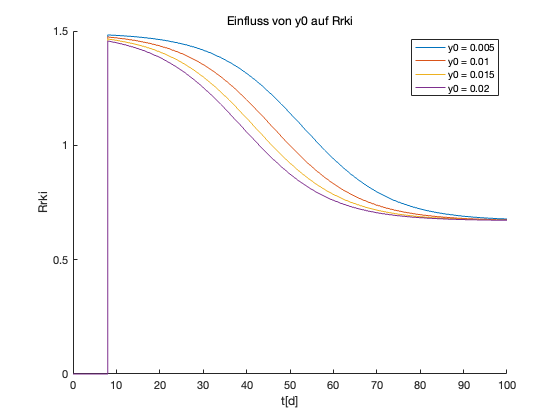


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{3}.Values)
    legendText_Rrki_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_Rrki_y0)
xlabel('t[d]')
ylabel('Rrki')
title('Einfluss von y0 auf Rrki')
saveas(gcf,fullfile('images', 'Rrki_y0'), 'jpeg')

%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
k = 0.05:0.05:0.2;

for p = 1:1:length(y0)
    in_Rrki_k(p) = Simulink.SimulationInput(model);
    in_Rrki_k(p) = in_Rrki_k(p).setVariable('y0', 0.01, 'Workspace', 'Ausbreitungsmodell');
    in_Rrki_k(p) = in_Rrki_k(p).setVariable('y0', k(p), 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_Rrki_k, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[14-Feb-2021 02:19:09] Checking for availability of parallel pool...
[14-Feb-2021 02:19:09] Running simulations...
[14-Feb-2021 02:19:09] Completed 1 of 4 simulation runs
[14-Feb-2021 02:19:09] Completed 2 of 4 simulation runs
[14-Feb-2021 02:19:10] Completed 3 of 4 simulation runs
[14-Feb-2021 02:19:10] Completed 4 of 4 simulation runs


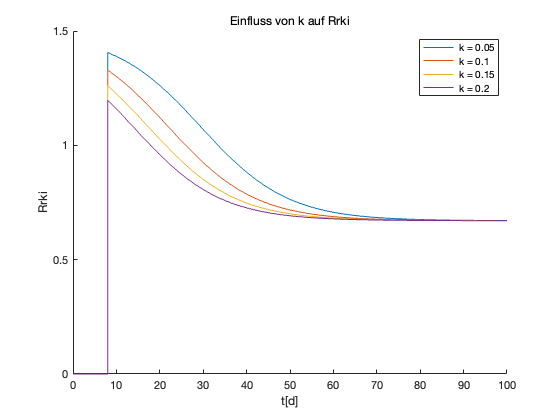


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{3}.Values)
    legendText_Rrki_k{p} = [' k = ', num2str(k(p))];
end
legend(legendText_Rrki_k)
xlabel('t[d]')
ylabel('Rrki')
title('Einfluss von k auf Rrki')
saveas(gcf,fullfile('images', 'Rrki_k'), 'jpeg')

#### 4. Implementieren Sie verschiedene Strategien zur Eindämmung der Infektion, z.B. ein Kontaktverbot 

Grundsätzlich bestehen zwei Möglichkeiten, denselben zu reduzieren:

- durch Reduktion der Replikationsrate r (Hygienemaßnahmen, Abstand usw.) und

- durch Reduktion der Gesunden durch Immunisierung (Impfung usw.), also Reduktion von N.

% LOAD MODEL
model_s = 'Eindaemmungsstrategien';
load_system(model_s)
%Simulink.BlockDiagram.buildRapidAcceleratorTarget(model);
%in_s = Simulink.SimulationInput(model_s);
%in = in.setModelParameter('SimulationMode', 'rapid-accelerator');
%in_s = in_s.setModelParameter('EndTime', 100);


#### 4.1 Reduktion der Replikationsrate r

Bekämpfungsstrategien, wie Lockdown, Abstandsregeln sowie sämtliche Hygienemaßnahmen lassen sich der Reduktion der Replikationsrate r zuordnen, was wir hier durch abrupte Änderung des k-Terms zu verschiedenen Zeitpunkt im Ablauf der Ausbreitung untersuchen wollen.

Da sich k in drei weitere Terme r, c, N aufschlüsseln lässt, ist hier lediglich eine qualitative Untersuchung möglich. Wir gehen davon aus, dass k durch die eingesetzte Strategie auf k/3 redurziert wird. Betrachtet werden 3 Zeitpunkt zum Einsetzen der Strategien: vor dem Wendepunkt, auf dem Wendepunkt, nach dem Wendepunkt. Zum Vergleich stellen wir noch eine Simulation ohne Eindämmung durch tk > 100s .

% PARAMETER VARIATION

%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
tk = [23;46;69;101];

for p = 1:1:length(tk)
    in_r(p) = Simulink.SimulationInput(model_s);
    in_r(p) = in_r(p).setVariable('tk', tk(p), 'Workspace', 'Eindaemmungsstrategien');
    in_r(p) = in_r(p).setVariable('r_strategie', 1, 'Workspace', 'Eindaemmungsstrategien');
    in_r(p) = in_r(p).setVariable('I_strategie', 0, 'Workspace', 'Eindaemmungsstrategien');
end

out = parsim(in_r, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[14-Feb-2021 02:19:11] Checking for availability of parallel pool...
[14-Feb-2021 02:19:11] Running simulations...
[14-Feb-2021 02:19:11] Completed 1 of 4 simulation runs
[14-Feb-2021 02:19:11] Completed 2 of 4 simulation runs
[14-Feb-2021 02:19:12] Completed 3 of 4 simulation runs
[14-Feb-2021 02:19:12] Completed 4 of 4 simulation runs


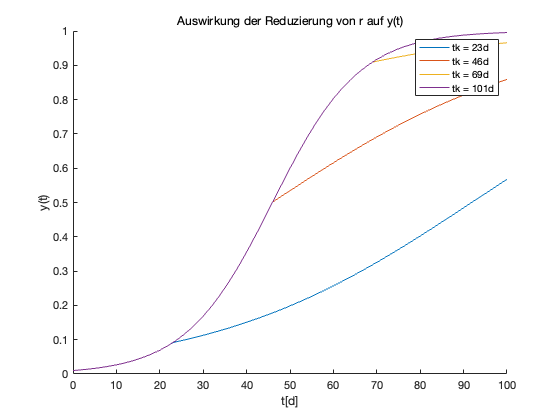


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText_tk{p} = ['tk = ', num2str(tk(p)), 'd'];
end
legend(legendText_tk)
xlabel('t[d]')
ylabel('y(t)')
title('Auswirkung der Reduzierung von r auf y(t)')
saveas(gcf,fullfile('images', 'yt_r'), 'jpeg')

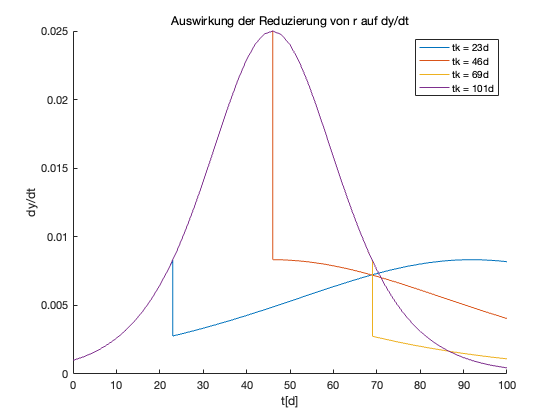


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_tk{p} = ['tk = ', num2str(tk(p)), 'd'];
end
legend(legendText_tk)
xlabel('t[d]')
ylabel('dy/dt')
title('Auswirkung der Reduzierung von r auf dy/dt')
saveas(gcf,fullfile('images', 'dydt_r'), 'jpeg')

#### 4.2 Immunisierung

Da die Auswirkung von Immunisierung nur schwer in dem einfachen SI-Modell analysiert werden kann, können wir die angegebene Gleichung mit einem zusätzlichen Term i erweitern. Der Term i bezeichnet den geimpften Bevölkerungsanteil pro Zeiteinheit (hier Tag). Hierzu wird angenommen dass die Immunisierung zum Simulationsanfang sofort beginnt. Die Größe von i lautet nach dem aktuellen Impfungszustand in Deutschland nach Abrundung 0.1%. Der Fokus der Analyse hier ist die Impfungsgeschwindigkeit, was durch die Variation von i dargestellt werden kann.

% PARAMETER VARIATION

%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');

i = 0.001:0.002:0.009;
for p = 1:1:length(i)
    in_I(p) = Simulink.SimulationInput(model_s);
    in_I(p) = in_I(p).setVariable('r_strategie', 0, 'Workspace', 'Eindaemmungsstrategien');
    in_I(p) = in_I(p).setVariable('I_strategie', 1, 'Workspace', 'Eindaemmungsstrategien');
    in_I(p) = in_I(p).setVariable('i', i(p), 'Workspace', 'Eindaemmungsstrategien');   
end

out = parsim(in_I, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[14-Feb-2021 02:19:13] Checking for availability of parallel pool...
[14-Feb-2021 02:19:13] Running simulations...
[14-Feb-2021 02:19:14] Completed 1 of 5 simulation runs
[14-Feb-2021 02:19:14] Completed 2 of 5 simulation runs
[14-Feb-2021 02:19:14] Completed 3 of 5 simulation runs
[14-Feb-2021 02:19:14] Completed 4 of 5 simulation runs
[14-Feb-2021 02:19:14] Completed 5 of 5 simulation runs


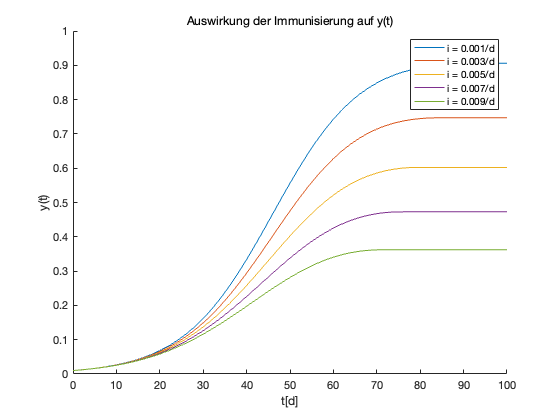


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText_I{p} = ['i = ', num2str(i(p)), '/d'];
end
legend(legendText_I)
xlabel('t[d]')
ylabel('y(t)')
title('Auswirkung der Immunisierung auf y(t)')
saveas(gcf,fullfile('images', 'yt_I'), 'jpeg')

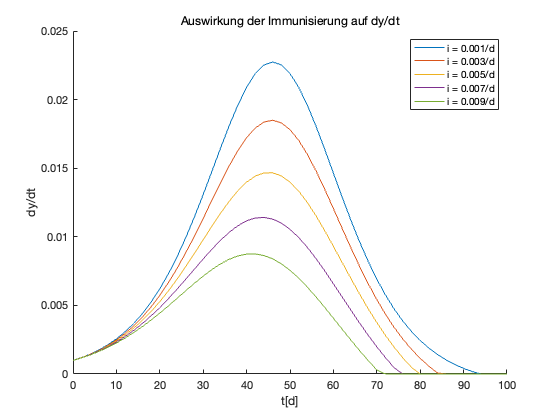


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_I{p} = ['i = ', num2str(i(p)), '/d'];
end
legend(legendText_I)
xlabel('t[d]')
ylabel('dy/dt')
title('Auswirkung der Immunisierung auf dy/dt')
saveas(gcf,fullfile('images', 'dydt_I'), 'jpeg')